## Définition des variables

Dans cette section nous allons définir les variables qui vons nous être utiles pour la modélisation. 

### Variables pour les degrées de libertés (DDL)

Le tableau suivant utilise la notation définie par SNAME(1950).

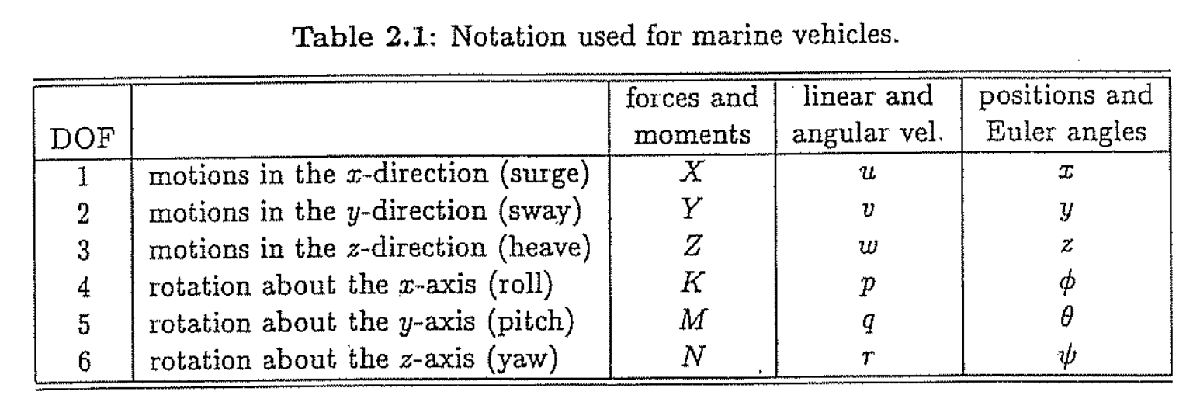

Étant donné que nous voulons utiliser les quaternions, nous n'allons pas définir les angles d'Euler

clear;
sympref('MatrixWithSquareBrackets',true)
    
% Définir les forces et moments
    syms X Y Z K M N
    syms Fm
    syms tauE
    
% Définir les vitesses linéaires et angulaires
    syms u v w p q r

% Définir les positions linéaires
    syms x y z
    
% Définir les entrées système (Thruster)
    syms ('U',[8,1])

% Définir les forces externes et perturbations
    syms ('F_ext',[6,1])
    
% Condition Initials
    syms ('P_0',[7,1])
    syms ('V_0',[6,1])

### Variables pour le quaternion

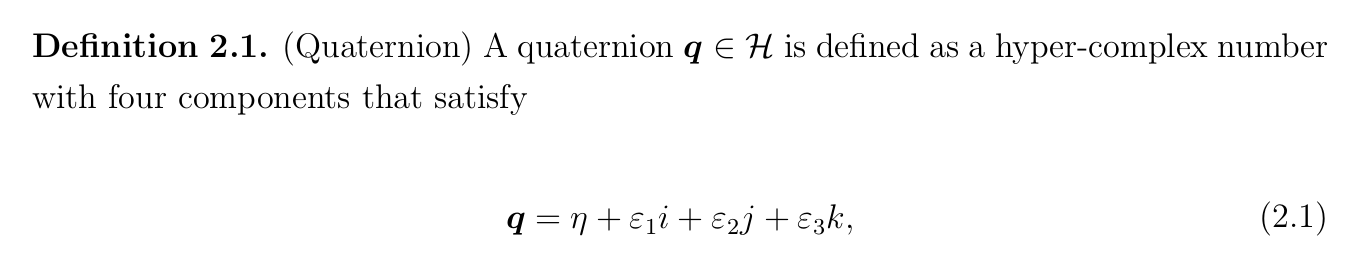

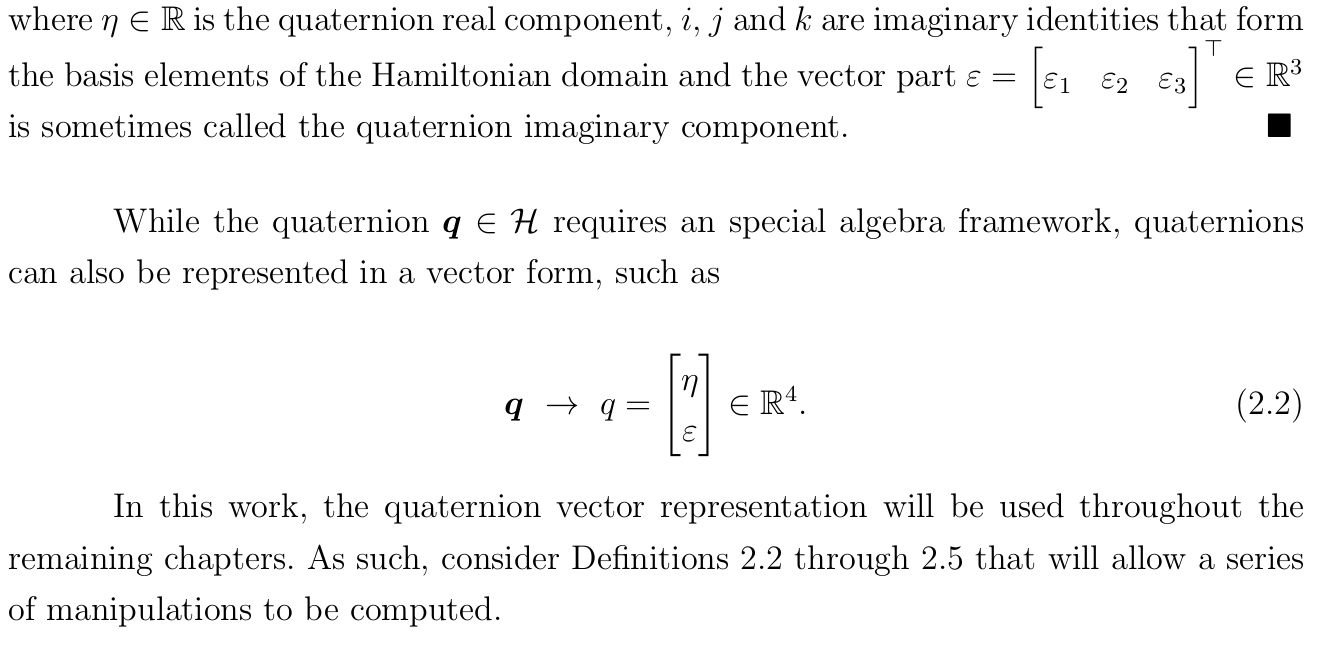

    % Définir la partie scalaire
        syms eta;
        
    % Définir la partie vectorielle
        syms('epsilon',[3,1]);
    
    % Définir le quaternion  
        e=[eta; epsilon];
        
  

### Constante du modèle physique

% distance truster x y z selon centre geommétrique (Constantes)
% D14 distance thruster 1 a 4. (Constantes)
% D58 distance thruster 5 a 8. (Constantes)
% a14 angle thruster 1 a 4. (Constantes)
% dz distance entre les increments sur le frame. (Constantes)
% PZ position des truster sur le frame. (Constantes)
    syms('D14',[1 3]); syms('D58',[1 3]) ; syms a14 dz ; syms ('PZ',[1,4]);

% masse, volume du prototype et hauteur sub (Constantes)
    syms mass volume height

% coefficient de drag (Constantes)
    syms ('CD_L',[1, 6])    % Lineaire
    syms ('CD_Q', [1, 6]);  % Quadratique

% aire de surface du sub (Constantes)
    syms ('AF', [1, 3]);

% matrice d'inertie (Constantes)
    syms ('I', [3, 3]);

% centre de gravité RG et centre de flotataison RB (Constantes)
    syms ('RG',[3 1]); syms('RB',[3 1])
    
% Constantes physique (densité de leau et accélération gravitationel)
    syms rho g


### Regroupement des variables

Nous allons par la suite regrouper les variables

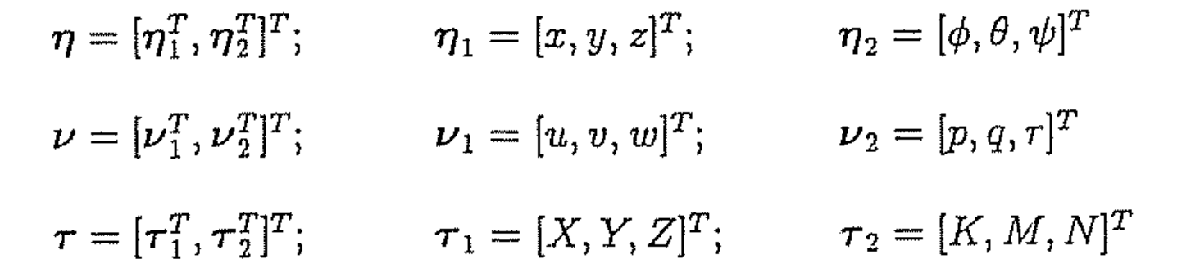

% Position et Orientation 
    n1= [x,y,z].';
    Ne=[n1;e]
    
% Vitesses
    v1=[u,v,w].';
    v2=[p,q,r].';
    V=[v1;v2]
    
% Forces et moments
   Fm=[X,Y,Z,K,M,N].';
   

% Constance Mecanique
   constMec = [D14 D58 a14 dz PZ mass volume height AF...
             I(1,:) I(2,:) I(3,:) RG.' RB.' CD_L CD_Q rho g];

         

## Équation cinématique du mouvement

### Transformation de la vitesse linéaire

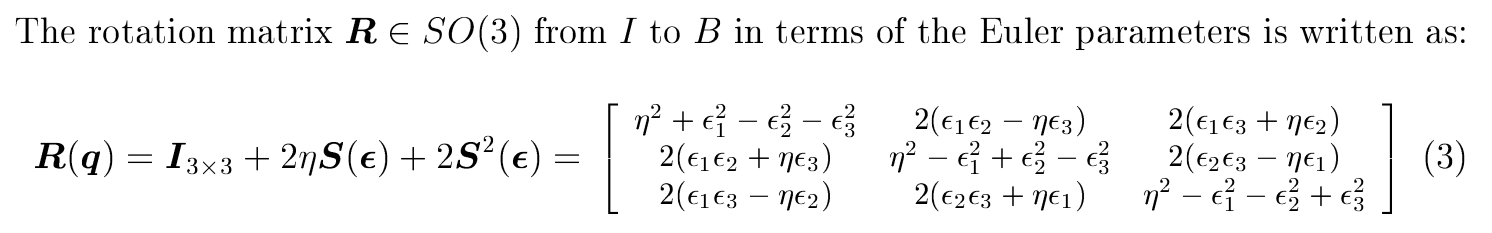

    % Équation 3
    E1=eye(3)+2*eta*skew(epsilon)+2*skew(epsilon)^2
    E1.'
    simplify(inv(E1))
    % Équation 2.24 (Fossen)
    EE1=[(eta^2-epsilon.'*epsilon)*eye(3)+2*epsilon*epsilon.'-2*eta*skew(epsilon)].'
  

### Transformation de la vitesse angulaire

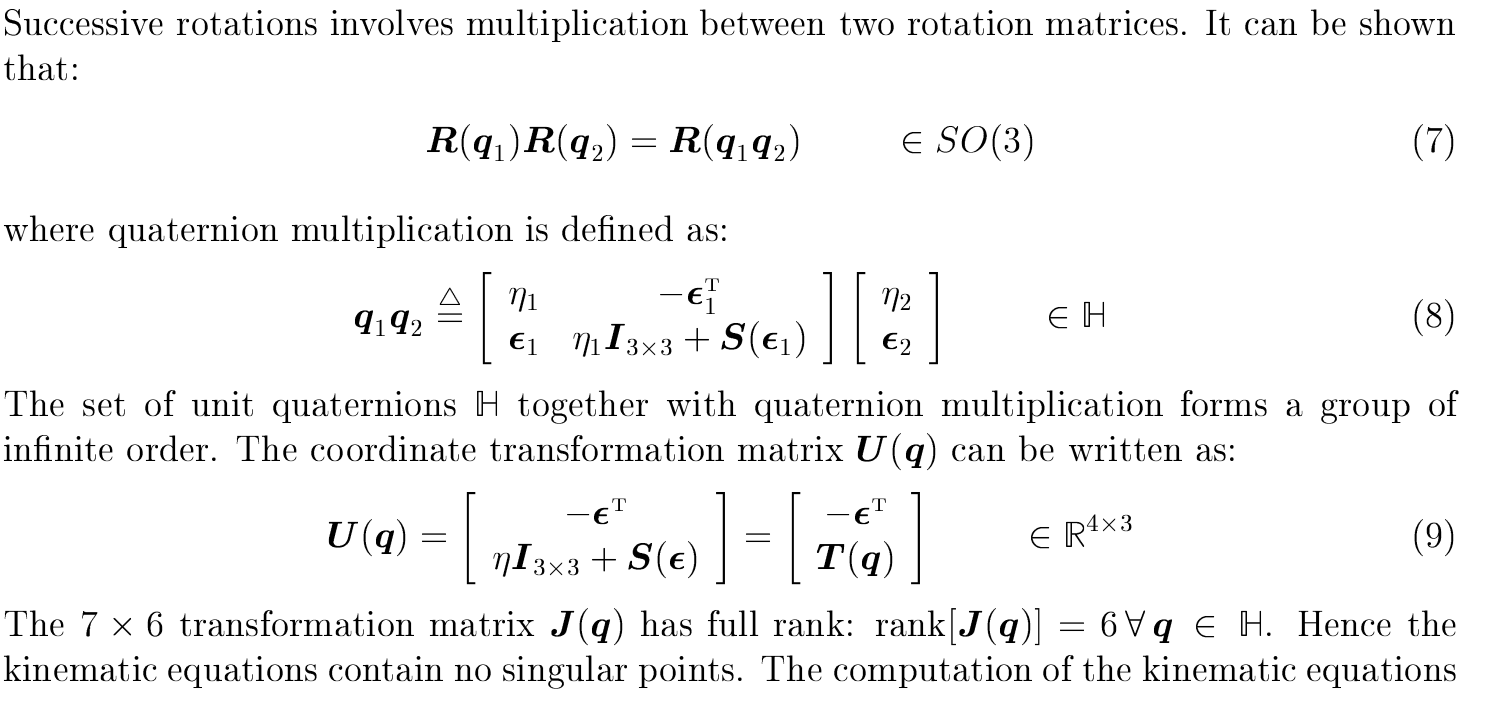

   E2=[-epsilon.';eta*eye(3)+skew(epsilon)]
   

### Matrice de transformation

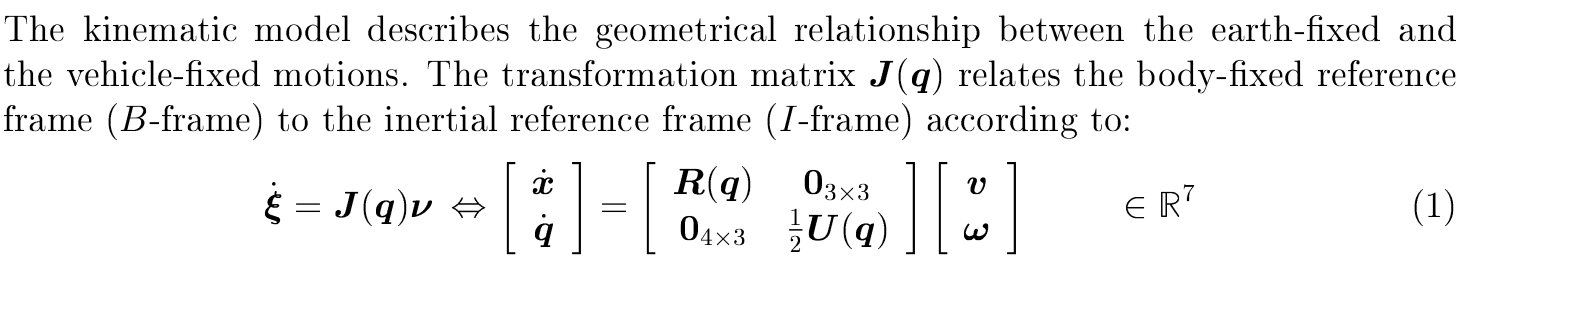

% Définir la matrice de transformation J(q)
   J=[EE1,zeros(3,3);
   zeros(4,3),(1/2)*E2]


## Équation dynamique d'un corps rigide

### Matrice des masses et d'inertie

% Corp rigide
Mrb=[mass*eye(3),-mass*skew(RG);
     mass*skew(RG),I ]
 
% Masse ajouté 
Ma1 = [zeros(3,3)];
Ma2 = [zeros(3,3)];
Ma3 = [zeros(3,3)];
Ma4 = [zeros(3,3)];

Ma = [Ma1,Ma2;
      Ma3,Ma4]
  
M = Mrb + Ma;

### Matrice de Coriolis

% Corp rigide
Crb= [zeros(3,3), -mass*skew(v1)- mass*skew(skew(v2)*RG);
     -mass*skew(v1)- mass*skew(skew(v2)*RG), skew(I*v2)+mass*skew(skew(v1)*RG)]

% Masse ajouté
Ca =[zeros(3,3), -skew(Ma1*v1+Ma2*v2);
     -skew(Ma1*v1+Ma2*v2), -skew(Ma3*v1+Ma4*v2)]
 
C = Crb + Ca

### Matrice de damping

% Equation quadratique de damping
xu = ((1/2) * rho * CD_Q1 * AF1 * abs(u));
yv = ((1/2) * rho * CD_Q2 * AF2 * abs(v));
zw = ((1/2) * rho * CD_Q3 * AF3 * abs(w));
kp = ((1/2) * rho * CD_Q4 * AF3 * abs(p));
mq = ((1/2) * rho * CD_Q5 * AF3 * abs(q));
nr = ((1/2) * rho * CD_Q6 * AF2 * abs(r));

% Matrice quadratic damping.
Dq = diag([xu yv zw kp mq nr])

% Matrice linear damping.
Dl = diag(CD_L);

D = (Dl + Dq);

### Matrice de gravité 

% Matrice de gravité

% Équation du volume submergé selon la profondeur z.     /͞ ͞
% Équation à double asymptote horizontal. Voir erf()  __/

% Calculs des constantes
aa= volume/2;   % Calculer l'amplitude.
kk=aa;          % Monter la courbe pour avoir min 0 et max volume.
bb=4/height;    % Calculer la pente transitoire.
hh=height/2;    % Décaler la courbe pour avoir x(0)=0. 

% Équation
vz=aa*erf(bb*(z-hh))+kk;

% Vecteur gravité
W = [0; 0; (mass * g)];

% Vecteur poussée d'Archimède
B = [0; 0; (rho * g * vz)];

FG = E1.' * W;
FB = E1.' * B;

Ge = [FB - FG;
    cross(RB, FB) - cross(RG, FG)]



### Matrice de moteurs

% Definir la matrice thrusters

% Thruster effort Mapping Matrix (L)
%             x         y      z      
l1 = [ sin(a14),-cos(a14), 0,... fxyz
    (D14(3)-RG(3)+PZ(1)*dz)*cos(a14),... rx
    (D14(3)-RG(3)+PZ(1)*dz)*sin(a14),... ry
    -hypot( D14(1)-RG(1), D14(2)-RG(2))]; %rz

l2 = [ sin(a14), cos(a14), 0,...fxyz
     -(D14(3)-RG(3)+PZ(2)*dz)*cos(a14),...rx
     (D14(3)-RG(3)+PZ(2)*dz)*sin(a14),...ry
     -hypot( D14(1)+RG(1), D14(2)-RG(2))];%rz

l3 = [ sin(a14),-cos(a14), 0,...fxyz
    (D14(3)-RG(3)+PZ(3)*dz)*cos(a14),...rx
     (D14(3)-RG(3)+PZ(3)*dz)*sin(a14),...ry
     hypot(D14(1)+RG(1), D14(2)+RG(2))];%rz

l4 = [ sin(a14), cos(a14), 0,...fxyz
    -(D14(3)-RG(3)+PZ(4)*dz)*cos(a14),...rx
     (D14(3)-RG(3)+PZ(4)*dz)*sin(a14),...ry
     hypot(D14(1)-RG(1), D14(2)+RG(2))];%rz

l5 = [0, 0, 1, (D58(2)-RG(2)+PZ(1)*dz),...
     -(D58(1)-RG(1)+PZ(1)*dz), 0];

l6 = [0, 0,-1,-(D58(2)-RG(2)+PZ(2)*dz),...
      -(D58(1)+RG(1)+PZ(2)*dz), 0];

l7 = [0, 0, 1,-(D58(2)+RG(2)+PZ(3)*dz),...
    (D58(1)+RG(1)+PZ(3)*dz), 0];

l8 = [0, 0,-1, (D58(2)+RG(2)+PZ(4)*dz),...
     (D58(1)-RG(1)+PZ(2)*dz), 0];

% Matrice thrusters
Tm = [l1.', l2.', l3.', l4.', l5.' l6.', l7.', l8.'];

### Sommes des forces et des moments

    %Fm = (Tm * U + tauE) - (C * V + D * V + Ge);

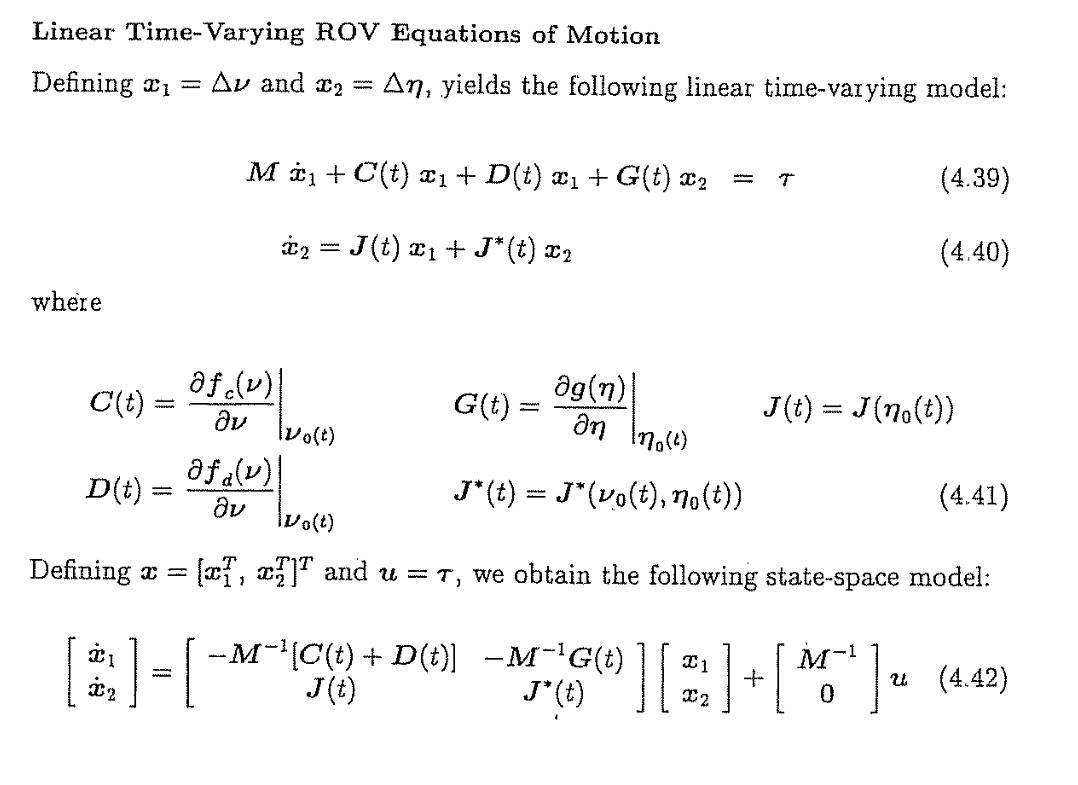

    % calcules des jacobiennes
    Dj = jacobian(D*V,V)
    Cj = jacobian(C*V,V)
    Gj = jacobian(Ge,Ne)
    Jj = jacobian(J*V,[Ne;V])
    
    sim(1:7)=J*V;
    sim(8:13)=-(M\Ge) - (M\(C*V + D*V)) + (M\(F_ext+(Tm*U)));
    
  
    Ac = [zeros(7,7),J;
         -(M\ Gj),-(M\(Cj + Dj))];
    
    Bc = [zeros(7,8);M\Tm];
    
    Cc = jacobian([e;V],[Ne;V]);
    
    Dc = jacobian([e;V], U );

## Implémentation 

### Substituer les constantes du modèle du sous-marin

%% Chargement des paramètres
    cf = ConfigAUV8();

    constValues = [cf.d14 ...
                 cf.d58 ...
                 cf.a14 ...
                 cf.dz ...
                 cf.z ...
                 cf.mass ...
                 cf.volume ...
                 cf.height...
                 cf.AF ...
                 cf.I(1,:) ...
                 cf.I(2,:) ...
                 cf.I(3,:) ...
                 cf.RG ...
                 cf.RB ...
                 cf.CDL...
                 cf.CDQ...
                 cf.rho ...
                 cf.g];

    
    sim=subs(sim, constMec, constValues);
    Gravity =subs(Ge, constMec, constValues);
    Thrust=subs(Tm, constMec, constValues);
    
    Av=subs(Ac, constMec, constValues);
    Bv=subs(Bc, constMec, constValues);


### Linéariser au condition initials.

    % États initaux
    N0=[0;0;.2246;1;0;0;0]
    V0=[0;0;0;0;0;0]
    
    A0=double(subs(Av, [Ne;V], [N0;V0]));   
    B0=double(Bv);

## Étude

Ts=0.1;
nx = size(A0,1);
nu = size(B0,2);
M = expm([[A0 B0]*Ts; zeros(nu,nu+nx)]);
Ad = M(1:nx,1:nx);
Bd = M(1:nx,nx+1:nx+nu);
Cd = double(Cc);
Dd = double(Dc);
AUVPlant=ss(Ad,Bd,Cd,Dd,Ts);

% Création du controleur MPC.
    mpcobj =mpc(AUVPlant);

% Étude de controllabilité
    c0=ctrb(A0,B0);
    nc=rank(c0)
    
% Étude de stabilité au point d'équilibre
    poles=eig(A0)


### Générer les fonctions matlab

% Générer l'équation non linéaire
    matlabFunction(transpose(sim),'File','AUVFossenSimFcn',...
       'Vars',{[Ne;V],F_ext,U});
   
% Générer les matrices jacobiennes
    matlabFunction(Av, Bv, Cc, Dc,'File','AUVJacobianMatrix',...
        'Vars',{[Ne;V]});  
    
% Générer les fonction pour la condition inital
    matlabFunction(Gravity, Thrust,'File','AUVKickInMatrix',...
        'Vars',{[Ne;V]});  


## Sous-fonctions personalisées

Ici ce trouve nos fonctions personalisées

### Matrice antisymétrique

function sm=skew(u) 
% Convertie un vecteur 3x1 en une matrice antisymétrique 3x3
    sm=[0,-u(3),u(2);
        u(3), 0, -u(1);
       -u(2), u(1), 0];
end